## Step 5 - 店舗タイプ別分析：多変量解析によるクラスタリング

% 目的: k-meansクラスタリングで店舗を4-5タイプに分類し、
%       各タイプの特徴と推奨戦略を提示する
% 
% 必要ファイル: step3_results.mat, step4_results.mat, rawData_dailySales

% clear; clc; close all;

### 1. データ読み込み

if ~exist('step3_results.mat', 'file')
    error('step3_results.mat が見つかりません。Step 3を先に実行してください。');
end

if ~exist('step4_results.mat', 'file')
    error('step4_results.mat が見つかりません。Step 4を先に実行してください。');
end

load('step3_results.mat', 'step3Results');
load('step4_results.mat', 'step4Results');

if ~exist('rawData_dailySales', 'var')
    error('rawData_dailySales が見つかりません。');
end

fprintf('  ✓ step3_results.mat を読み込みました\n');

  ✓ step3_results.mat を読み込みました


fprintf('  ✓ step4_results.mat を読み込みました\n');

  ✓ step4_results.mat を読み込みました


fprintf('  ✓ rawData_dailySales を読み込みました\n\n');

  ✓ rawData_dailySales を読み込みました




storeMetrics = step4Results.storeMetrics;
storeList = storeMetrics.storeCode;
nStores = length(storeList);
validStores = step3Results.storeValidFlags;

### 2. クラスタリング用特徴量の作成

% 特徴量の選択（7変数）
featureMatrix = [
    storeMetrics.totalSales, ...           % 1. 総売上
    storeMetrics.patternSimilarity, ...    % 2. パターン一致度
    storeMetrics.salesPerCustomer, ...     % 3. 客単価
    storeMetrics.topCategoryShare, ...     % 4. TOP1カテゴリシェア（集中度）
    storeMetrics.nCategories, ...          % 5. 取扱カテゴリ数
    storeMetrics.nActiveDays, ...          % 6. 営業日数
    storeMetrics.avgDailySales             % 7. 日平均売上
];

featureNames = {
    '総売上', ...
    'パターン一致度', ...
    '客単価', ...
    'TOP1シェア', ...
    'カテゴリ数', ...
    '営業日数', ...
    '日平均売上'
};

% 欠損値や無効値のチェック
validIdx = validStores & all(~isnan(featureMatrix), 2) & ...
           all(~isinf(featureMatrix), 2) & ...
           storeMetrics.salesPerCustomer > 0;

fprintf('  有効店舗数: %d / %d\n', sum(validIdx), nStores);

  有効店舗数: 35 / 35



% 有効店舗のみ抽出
validStoreList = storeList(validIdx);
validFeatures = featureMatrix(validIdx, :);
nValidStores = sum(validIdx);

% 特徴量の正規化（z-score）
normalizedFeatures = zscore(validFeatures);

fprintf('  ✓ 7変数の特徴量を作成しました\n');

  ✓ 7変数の特徴量を作成しました


fprintf('  ✓ z-scoreで正規化しました\n\n');

  ✓ z-scoreで正規化しました



### 3. PCA（可視化用の次元削減）

[coeff, score, ~, ~, explained] = pca(normalizedFeatures);
pc2D = score(:, 1:2);  % 第1-2主成分

fprintf('  第1主成分の寄与率: %.1f%%\n', explained(1));

  第1主成分の寄与率: 42.9%


fprintf('  第2主成分の寄与率: %.1f%%\n', explained(2));

  第2主成分の寄与率: 25.3%


fprintf('  累積寄与率: %.1f%%\n\n', sum(explained(1:2)));

  累積寄与率: 68.2%



### 4. 最適クラスタ数の決定

maxK = 8;
minK = 2;
kRange = minK:maxK;
nTrials = length(kRange);

sse = zeros(nTrials, 1);
silhouetteScores = zeros(nTrials, 1);

for i = 1:nTrials
    k = kRange(i);
    [idx, C, sumd] = kmeans(normalizedFeatures, k, ...
        'Replicates', 50, 'MaxIter', 500, 'Distance', 'sqeuclidean');
    
    sse(i) = sum(sumd);
    silhouetteScores(i) = mean(silhouette(normalizedFeatures, idx));
    
    fprintf('  k=%d: SSE=%.2f, Silhouette=%.3f\n', k, sse(i), silhouetteScores(i));
end

  k=2: SSE=167.64, Silhouette=0.775
  k=3: SSE=121.20, Silhouette=0.546
  k=4: SSE=82.84, Silhouette=0.605
  k=5: SSE=60.70, Silhouette=0.603
  k=6: SSE=47.80, Silhouette=0.431
  k=7: SSE=39.04, Silhouette=0.446
  k=8: SSE=33.38, Silhouette=0.453



% 最適kの決定（シルエット係数が最大）
[~, optimalIdx] = max(silhouetteScores);
optimalK = kRange(optimalIdx);

fprintf('\n  推奨クラスタ数: k = %d （シルエット係数: %.3f）\n\n', ...
    optimalK, silhouetteScores(optimalIdx));


  推奨クラスタ数: k = 2 （シルエット係数: 0.775）



### 5. k-meansクラスタリング実行

[clusterIdx, centroids, sumd] = kmeans(normalizedFeatures, optimalK, ...
    'Replicates', 100, 'MaxIter', 1000, 'Distance', 'sqeuclidean');

fprintf('  ✓ クラスタリング完了\n\n');

  ✓ クラスタリング完了



### 6. タイプ別統計量の計算

storeTypes = struct();
storeTypes.clusterIdx = clusterIdx;
storeTypes.nClusters = optimalK;
storeTypes.centroids = centroids;

for k = 1:optimalK
    typeIdx = clusterIdx == k;
    nStoresInType = sum(typeIdx);
    
    fprintf('--- タイプ%d（%d店舗）---\n', k, nStoresInType);
    
    % 各特徴量の平均値
    typeMean = mean(validFeatures(typeIdx, :), 1);
    typeStd = std(validFeatures(typeIdx, :), 0, 1);
    
    fprintf('  平均値:\n');
    for f = 1:length(featureNames)
        fprintf('    %s: %.2f (±%.2f)\n', featureNames{f}, ...
            typeMean(f), typeStd(f));
    end
    
    % 代表店舗（重心に最も近い店舗）
    typeStores = validStoreList(typeIdx);
    typeFeatures = normalizedFeatures(typeIdx, :);
    centroid = centroids(k, :);
    
    distances = sqrt(sum((typeFeatures - centroid).^2, 2));
    [~, repIdx] = min(distances);
    representativeStore = typeStores(repIdx);
    
    fprintf('  代表店舗: 店舗%d\n', representativeStore);
    
    % 店舗リスト
    fprintf('  所属店舗: ');
    fprintf('%d ', typeStores);
    fprintf('\n\n');
    
    % 構造体に保存
    storeTypes.(['type' num2str(k)]) = struct(...
        'stores', typeStores, ...
        'mean', typeMean, ...
        'std', typeStd, ...
        'representative', representativeStore ...
    );
end

--- タイプ1（33店舗）---


  平均値:


    総売上: 141666.03 (±65184.71)
    パターン一致度: 0.74 (±0.13)
    客単価: 1.74 (±0.21)
    TOP1シェア: 0.31 (±0.11)
    カテゴリ数: 240.52 (±468.01)
    営業日数: 364.97 (±1.47)
    日平均売上: 388.27 (±179.03)


  代表店舗: 店舗15


  所属店舗: 

1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 28 29 30 31 32 33 34 35 

--- タイプ2（2店舗）---


  平均値:


    総売上: 10296.50 (±2628.32)
    パターン一致度: 0.13 (±0.13)
    客単価: 1.41 (±0.13)
    TOP1シェア: 0.27 (±0.00)
    カテゴリ数: 124.00 (±130.11)
    営業日数: 252.00 (±14.14)
    日平均売上: 41.22 (±12.74)


  代表店舗: 店舗26


  所属店舗: 

26 27 

### 7. タイプ別カテゴリ構成の分析

uniqueCategories = unique(rawData_dailySales.MajorCategory);
nCategories = length(uniqueCategories);

typeCategoryComposition = zeros(optimalK, nCategories);

for k = 1:optimalK
    typeStores = storeTypes.(['type' num2str(k)]).stores;
    
    % このタイプの全店舗のデータを集計
    typeData = rawData_dailySales(...
        ismember(rawData_dailySales.BookstoreCode, typeStores), :);
    
    % カテゴリ別売上
    for c = 1:nCategories
        catData = typeData(typeData.MajorCategory == uniqueCategories(c), :);
        typeCategoryComposition(k, c) = sum(catData.POSSalesVolume);
    end
    
    % 比率に変換
    typeCategoryComposition(k, :) = typeCategoryComposition(k, :) / ...
        sum(typeCategoryComposition(k, :));
end

storeTypes.categoryComposition = typeCategoryComposition;
storeTypes.categoryNames = uniqueCategories;

fprintf('  ✓ タイプ別カテゴリ構成を計算しました\n\n');

  ✓ タイプ別カテゴリ構成を計算しました



### 8. 階層クラスタリング（参考）

linkageTree = linkage(normalizedFeatures, 'ward');

fprintf('  ✓ デンドログラム用データを作成しました\n\n');

  ✓ デンドログラム用データを作成しました



### 9. 可視化

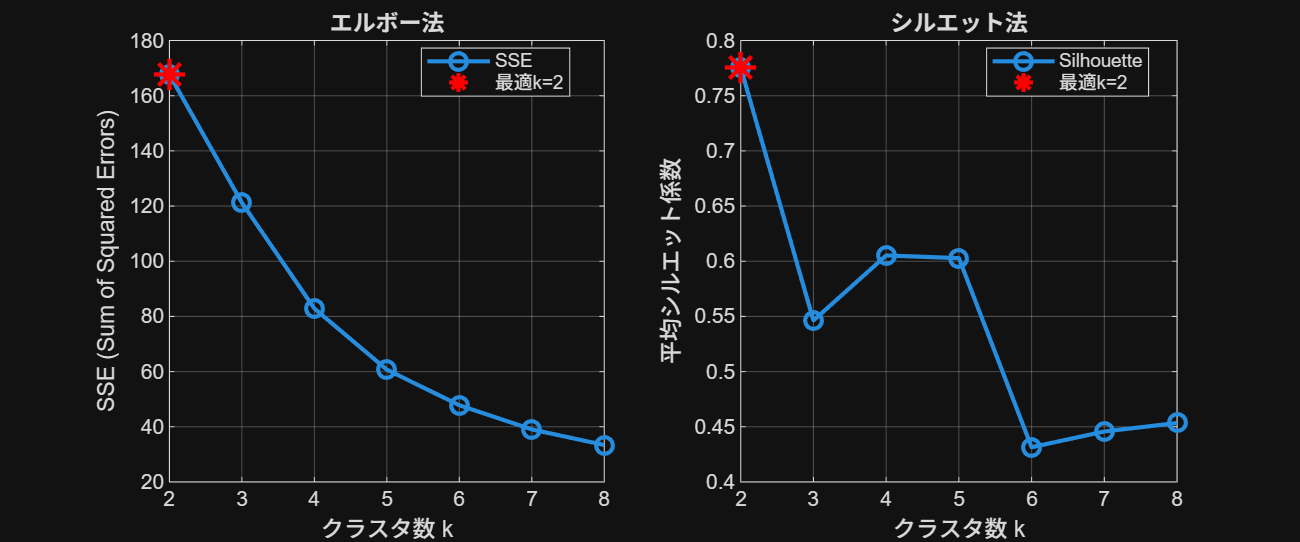

% 出力ディレクトリの作成
outputDir = 'figures_step5';
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

% ===== 図1: 最適クラスタ数の決定 =====
fig1 = figure('Name', '最適クラスタ数の決定', 'Position', [100 100 1200 500]);

subplot(1, 2, 1);
plot(kRange, sse, 'o-', 'LineWidth', 2, 'MarkerSize', 8);
xlabel('クラスタ数 k');
ylabel('SSE (Sum of Squared Errors)');
title('エルボー法');
grid on;
hold on;
plot(optimalK, sse(optimalIdx), 'r*', 'MarkerSize', 15, 'LineWidth', 2);
legend('SSE', sprintf('最適k=%d', optimalK), 'Location', 'best');

subplot(1, 2, 2);
plot(kRange, silhouetteScores, 'o-', 'LineWidth', 2, 'MarkerSize', 8);
xlabel('クラスタ数 k');
ylabel('平均シルエット係数');
title('シルエット法');
grid on;
hold on;
plot(optimalK, silhouetteScores(optimalIdx), 'r*', ...
    'MarkerSize', 15, 'LineWidth', 2);
legend('Silhouette', sprintf('最適k=%d', optimalK), 'Location', 'best');

saveas(fig1, fullfile(outputDir, 'fig1_最適クラスタ数決定.png'));

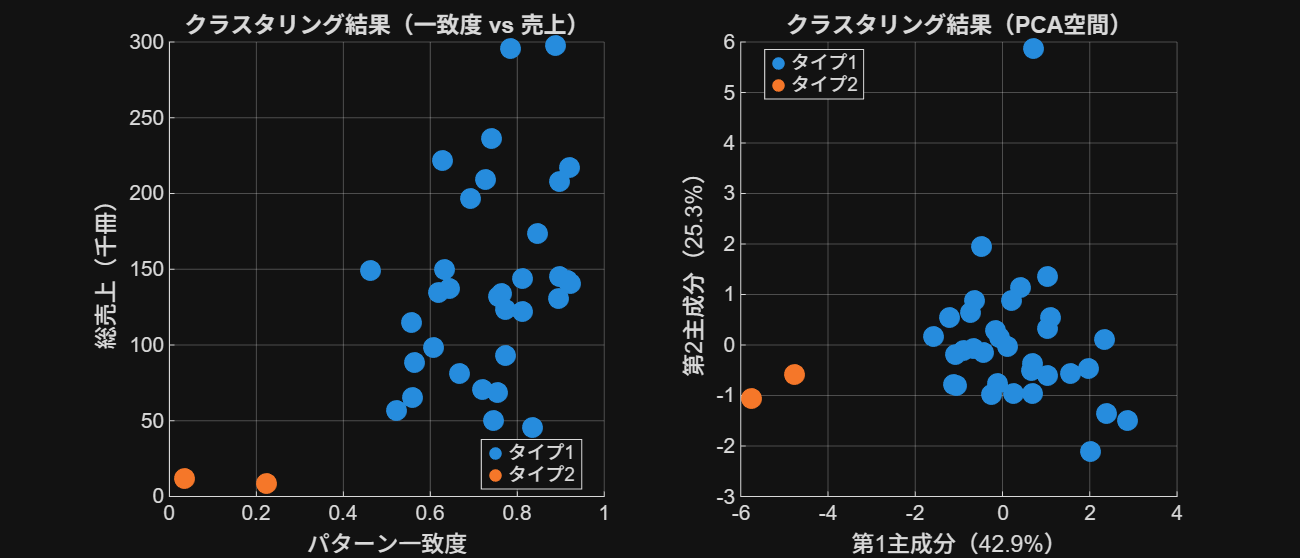


% ===== 図2: クラスタリング結果の散布図 =====
fig2 = figure('Name', 'クラスタリング結果', 'Position', [120 120 1400 600]);

colorMap = lines(optimalK);

% サブプロット1: 一致度 vs 売上
subplot(1, 2, 1);
hold on;
for k = 1:optimalK
    typeIdx = clusterIdx == k;
    scatter(validFeatures(typeIdx, 2), validFeatures(typeIdx, 1)/1000, ...
        100, colorMap(k, :), 'filled');
end
xlabel('パターン一致度');
ylabel('総売上（千冊）');
title('クラスタリング結果（一致度 vs 売上）');
legend(arrayfun(@(x) sprintf('タイプ%d', x), 1:optimalK, 'UniformOutput', false), ...
    'Location', 'best');
grid on;

% サブプロット2: PC1 vs PC2
subplot(1, 2, 2);
hold on;
for k = 1:optimalK
    typeIdx = clusterIdx == k;
    scatter(pc2D(typeIdx, 1), pc2D(typeIdx, 2), ...
        100, colorMap(k, :), 'filled');
end
xlabel(sprintf('第1主成分（%.1f%%）', explained(1)));
ylabel(sprintf('第2主成分（%.1f%%）', explained(2)));
title('クラスタリング結果（PCA空間）');
legend(arrayfun(@(x) sprintf('タイプ%d', x), 1:optimalK, 'UniformOutput', false), ...
    'Location', 'best');
grid on;

saveas(fig2, fullfile(outputDir, 'fig2_クラスタリング結果.png'));

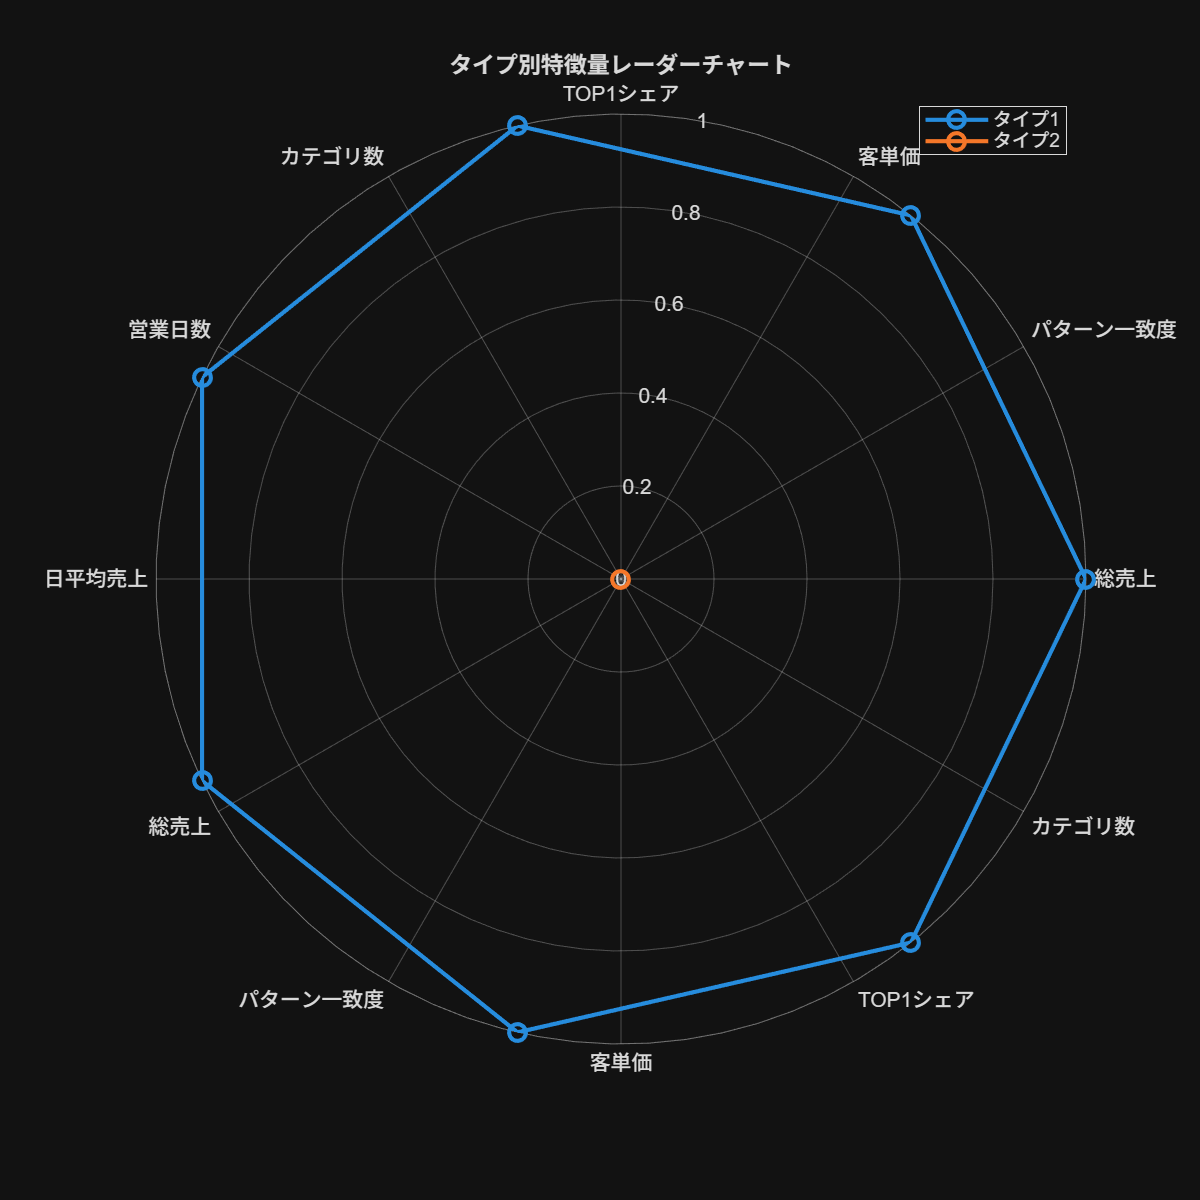


% ===== 図3: タイプ別レーダーチャート =====
fig3 = figure('Name', 'タイプ別レーダーチャート', 'Position', [140 140 800 800]);

% 特徴量を0-1に正規化（レーダーチャート用）
normalizedCentroids = (centroids - min(centroids)) ./ ...
    (max(centroids) - min(centroids) + eps);

angles = linspace(0, 2*pi, length(featureNames)+1);

% polaraxesを明示的に作成
pax = polaraxes;
hold(pax, 'on');

for k = 1:optimalK
    values = [normalizedCentroids(k, :), normalizedCentroids(k, 1)];
    polarplot(pax, angles, values, 'o-', 'LineWidth', 2, ...
        'Color', colorMap(k, :), 'MarkerSize', 8);
end

pax.ThetaTickLabel = featureNames;
title(pax, 'タイプ別特徴量レーダーチャート');
legend(pax, arrayfun(@(x) sprintf('タイプ%d', x), 1:optimalK, 'UniformOutput', false), ...
    'Location', 'best');
hold(pax, 'off');

saveas(fig3, fullfile(outputDir, 'fig3_レーダーチャート.png'));

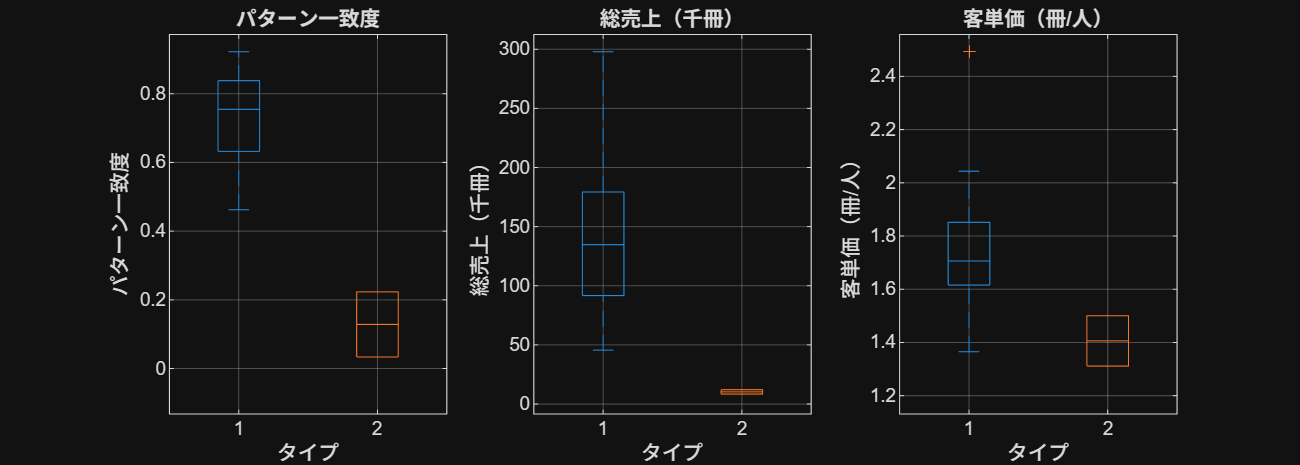


% ===== 図4: タイプ別箱ひげ図 =====
fig4 = figure('Name', 'タイプ別箱ひげ図', 'Position', [160 160 1400 500]);

metricsForBoxplot = [2, 1, 3];  % 一致度、売上、客単価
metricTitles = {'パターン一致度', '総売上（千冊）', '客単価（冊/人）'};

for m = 1:3
    subplot(1, 3, m);
    
    data = [];
    groups = [];
    for k = 1:optimalK
        typeIdx = clusterIdx == k;
        values = validFeatures(typeIdx, metricsForBoxplot(m));
        
        if m == 2  % 売上は千冊単位
            values = values / 1000;
        end
        
        data = [data; values];
        groups = [groups; repmat(k, sum(typeIdx), 1)];
    end
    
    boxplot(data, groups, 'Colors', colorMap);
    ylabel(metricTitles{m});
    xlabel('タイプ');
    title(metricTitles{m});
    grid on;
end

saveas(fig4, fullfile(outputDir, 'fig4_箱ひげ図.png'));

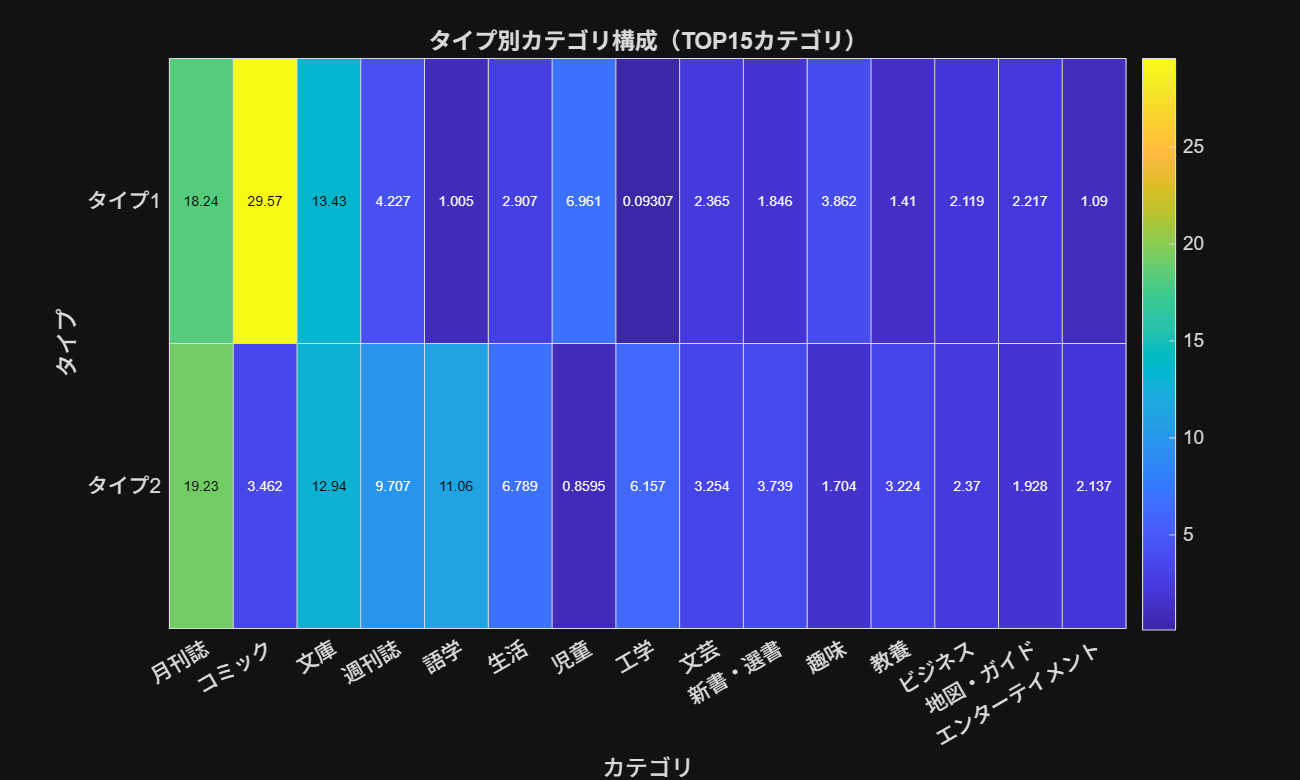


% ===== 図5: タイプ別カテゴリ構成ヒートマップ =====
fig5 = figure('Name', 'タイプ別カテゴリ構成', 'Position', [180 180 1000 600]);

% TOP15カテゴリを抽出
totalSales = sum(typeCategoryComposition, 1);
[~, sortIdx] = sort(totalSales, 'descend');
top15Idx = sortIdx(1:min(15, nCategories));

heatmapData = typeCategoryComposition(:, top15Idx) * 100;  % パーセント表示
categoryLabels = cellstr(string(uniqueCategories(top15Idx)));
typeLabels = arrayfun(@(x) sprintf('タイプ%d', x), 1:optimalK, 'UniformOutput', false);

h = heatmap(categoryLabels, typeLabels, heatmapData);
h.Title = 'タイプ別カテゴリ構成（TOP15カテゴリ）';
h.XLabel = 'カテゴリ';
h.YLabel = 'タイプ';
h.ColorbarVisible = 'on';
h.Colormap = parula;

saveas(fig5, fullfile(outputDir, 'fig5_カテゴリ構成ヒートマップ.png'));

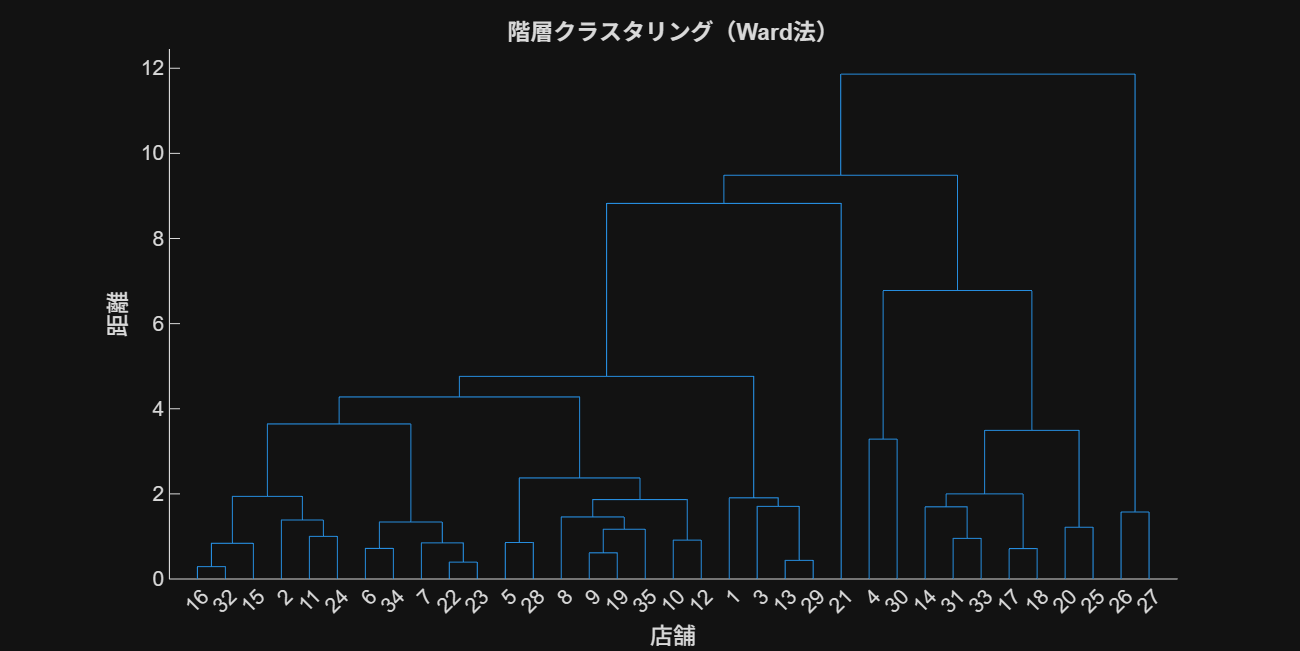


% ===== 図6: デンドログラム =====
fig6 = figure('Name', 'デンドログラム', 'Position', [200 200 1200 600]);

dendrogram(linkageTree, 0, 'Labels', cellstr(num2str(validStoreList)));
title('階層クラスタリング（Ward法）');
xlabel('店舗');
ylabel('距離');

saveas(fig6, fullfile(outputDir, 'fig6_デンドログラム.png'));


fprintf('  ✓ 6つの図を保存しました（%s/）\n\n', outputDir);

  ✓ 6つの図を保存しました（figures_step5/）



### 10. 推奨戦略の表示

for k = 1:optimalK
    typeData = storeTypes.(['type' num2str(k)]);
    typeMean = typeData.mean;
    
    fprintf('【タイプ%d】（%d店舗）\n', k, length(typeData.stores));
    fprintf('  平均一致度: %.3f\n', typeMean(2));
    fprintf('  平均売上: %.0f冊\n', typeMean(1));
    fprintf('  平均客単価: %.2f冊/人\n', typeMean(3));
    fprintf('  代表店舗: 店舗%d\n', typeData.representative);
    
    % 戦略の決定
    similarity = typeMean(2);
    sales = typeMean(1);
    
    fprintf('\n  【推奨戦略】\n');
    if similarity > 0.7 && sales > 150000
        fprintf('    ★ セレンディピティ型（高一致度・高売上）\n');
        fprintf('    → 現状維持、ベストプラクティスとして他店舗に共有\n');
        fprintf('    → 更なる顧客体験向上施策の実験店舗として活用\n');
    elseif similarity >= 0.5 && similarity <= 0.7
        fprintf('    ■ 標準型（中一致度）\n');
        fprintf('    → レイアウト最適化で売上向上の余地あり\n');
        fprintf('    → 提案レイアウトの段階的導入を推奨\n');
    elseif similarity < 0.5 && sales > 50000
        fprintf('    ▲ 改善余地型（低一致度・中売上）\n');
        fprintf('    → 積極的なレイアウト改善を推奨\n');
        fprintf('    → 相関分析に基づく配置変更で大きな効果が期待できる\n');
    elseif similarity < 0.2
        fprintf('    ◆ 特殊型（極低一致度）\n');
        fprintf('    → 大学書店等の特殊業態の可能性\n');
        fprintf('    → 独自戦略（目的買い特化）を推奨\n');
        fprintf('    → セレンディピティ型配置は不適合\n');
    else
        fprintf('    ● その他\n');
        fprintf('    → 個別の詳細分析が必要\n');
    end
    
    fprintf('\n');
end

【タイプ1】（33店舗）


  平均一致度: 0.737


  平均売上: 141666冊


  平均客単価: 1.74冊/人


  代表店舗: 店舗15



  【推奨戦略】


    ● その他


    → 個別の詳細分析が必要


【タイプ2】（2店舗）


  平均一致度: 0.128


  平均売上: 10296冊


  平均客単価: 1.41冊/人


  代表店舗: 店舗26



  【推奨戦略】


    ◆ 特殊型（極低一致度）


    → 大学書店等の特殊業態の可能性


    → 独自戦略（目的買い特化）を推奨


    → セレンディピティ型配置は不適合


### 11. 結果の保存

step5Results = struct();
step5Results.storeTypes = storeTypes;
step5Results.validStoreList = validStoreList;
step5Results.clusterIdx = clusterIdx;
step5Results.optimalK = optimalK;
step5Results.centroids = centroids;
step5Results.pc2D = pc2D;
step5Results.explained = explained;
step5Results.featureNames = featureNames;
step5Results.normalizedFeatures = normalizedFeatures;
step5Results.validFeatures = validFeatures;
step5Results.sse = sse;
step5Results.silhouetteScores = silhouetteScores;
step5Results.kRange = kRange;

save('step5_results.mat', 'step5Results');

fprintf('  ✓ 結果を step5_results.mat に保存しました\n');

  ✓ 結果を step5_results.mat に保存しました


fprintf('  ✓ 図を %s/ に保存しました\n\n', outputDir);

  ✓ 図を figures_step5/ に保存しました




fprintf('========================================\n');

fprintf('=== Step 5 完了 ===\n');

=== Step 5 完了 ===


fprintf('========================================\n');